## Compressed sensing in the spatial domain

The goal of this script is to demonstration compressed sensing image reconstruction of a synthetically generated ISAR image using Orthogonal Matching Pursuit (OMP). The image is extracted and a randomly sampled mask is applied to the image. 

Begin by extracting the ISAR image generated using run_simple_isar_bp. Apply a 2D Fourier transform to transform from the spatial domain to the spatial frequency domain. 

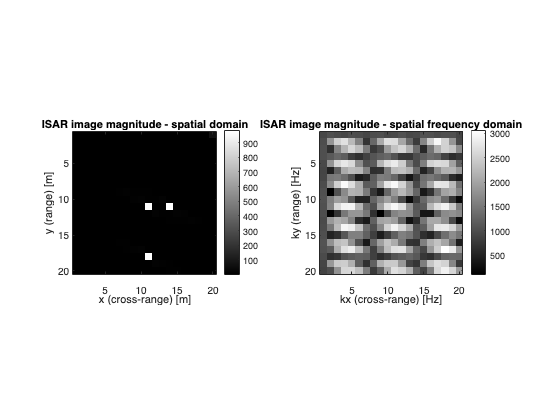

rng(0)

% load 2D ISAR image
x = load('data/rx_signal_bp_sd.mat');
x = x.rx_signal_bp;

% convert to the SFD
X = fftshift(fft2(x));

f = figure;
subplot(1,2,1)
imagesc(abs(x))
colormap("gray")
colorbar
xlabel('x (cross-range) [m]')
ylabel('y (range) [m]')
axis square
title('ISAR image magnitude - spatial domain')

subplot(1,2,2)
imagesc(abs(X))
colormap("gray")
colorbar
xlabel('kx (cross-range) [Hz]')
ylabel('ky (range) [Hz]')
axis square
title('ISAR image magnitude - spatial frequency domain')

%saveas(f,'plots/sd_and_sfd.png')


Generate a randomly sampled mask and apply it to the image in the spatial domain.

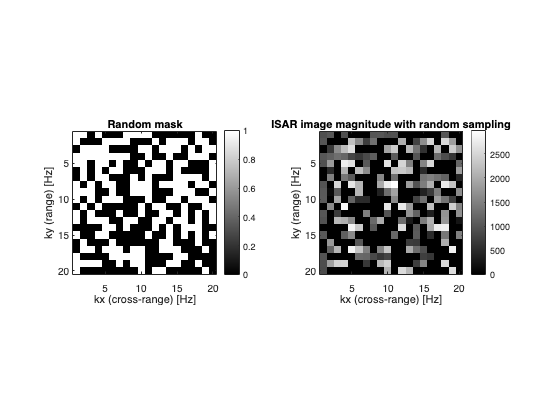

% extract dimensions from image
N = size(x,1);

% randomly sample image (k-space)
mask = rand(N);
mask = mask > 0.5;

% apply mask to k-space image
X_sampled = mask .* X;

figure
subplot(1,2,1)
imagesc(mask)
colormap("gray")
colorbar
xlabel('kx (cross-range) [Hz]')
ylabel('ky (range) [Hz]')
axis square
title('Random mask')

subplot(1,2,2)
imagesc(abs(X_sampled))
colormap("gray")
colorbar
xlabel('kx (cross-range) [Hz]')
ylabel('ky (range) [Hz]')
axis square
title('ISAR image magnitude with random sampling')

% formulate the measured signal y = Ax + n where A is the
% system or sensing matrix, y is the measurement, x is the
% signal and n is the noise

F = (1/sqrt(N)) * fft(eye(N));
Psi = conj(F);

x = real(Psi * X);

Phi = rand(m,N) / sqrt(m);

A = Phi * Psi;

% calculate the measurement
y = A * X + sigma * randn(m, 1);

f=figure;
subplot(1,2,1)
stem(-N/2:N/2-1, fftshift(abs(X)), 'LineWidth',2)
title('Truth signal','FontSize',24)
xlabel('frequency (Hz)','FontSize',16)
ylabel('magnitude','FontSize',16)

subplot(1,2,2)
stem(x, 'LineWidth',2)
title('Truth signal','FontSize',24)
xlabel('time (s)','FontSize',16)
ylabel('magnitude','FontSize',16)
set(gcf, 'Position', get(0, 'Screensize'));
saveas(f,'plots/truth_fft.png')

figure
stem(y, 'LineWidth',2)

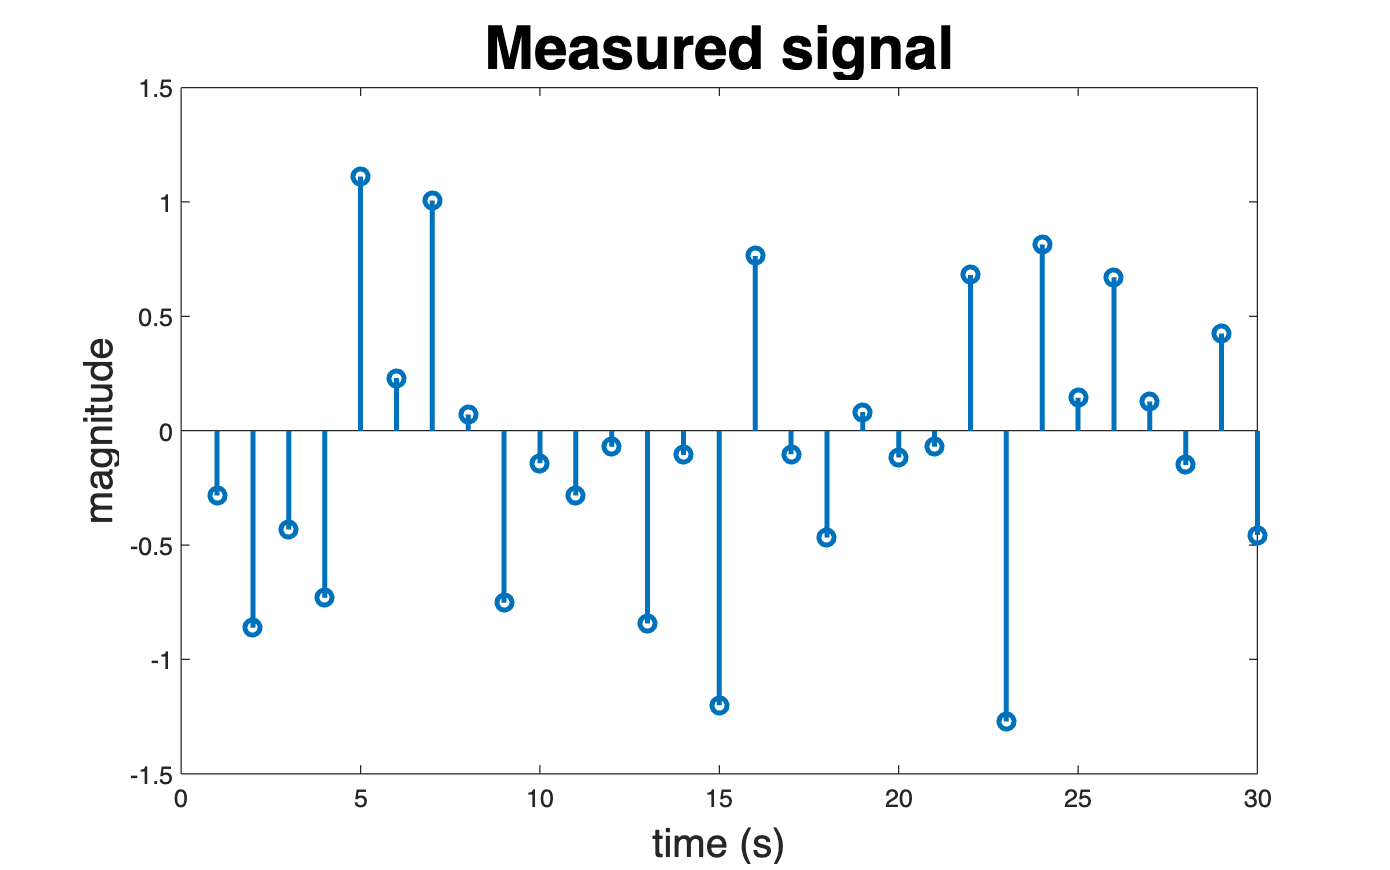

title('Measured signal','FontSize',24)
xlabel('time (s)','FontSize',16)
ylabel('magnitude','FontSize',16)
set(gcf, 'Position', get(0, 'Screensize'));

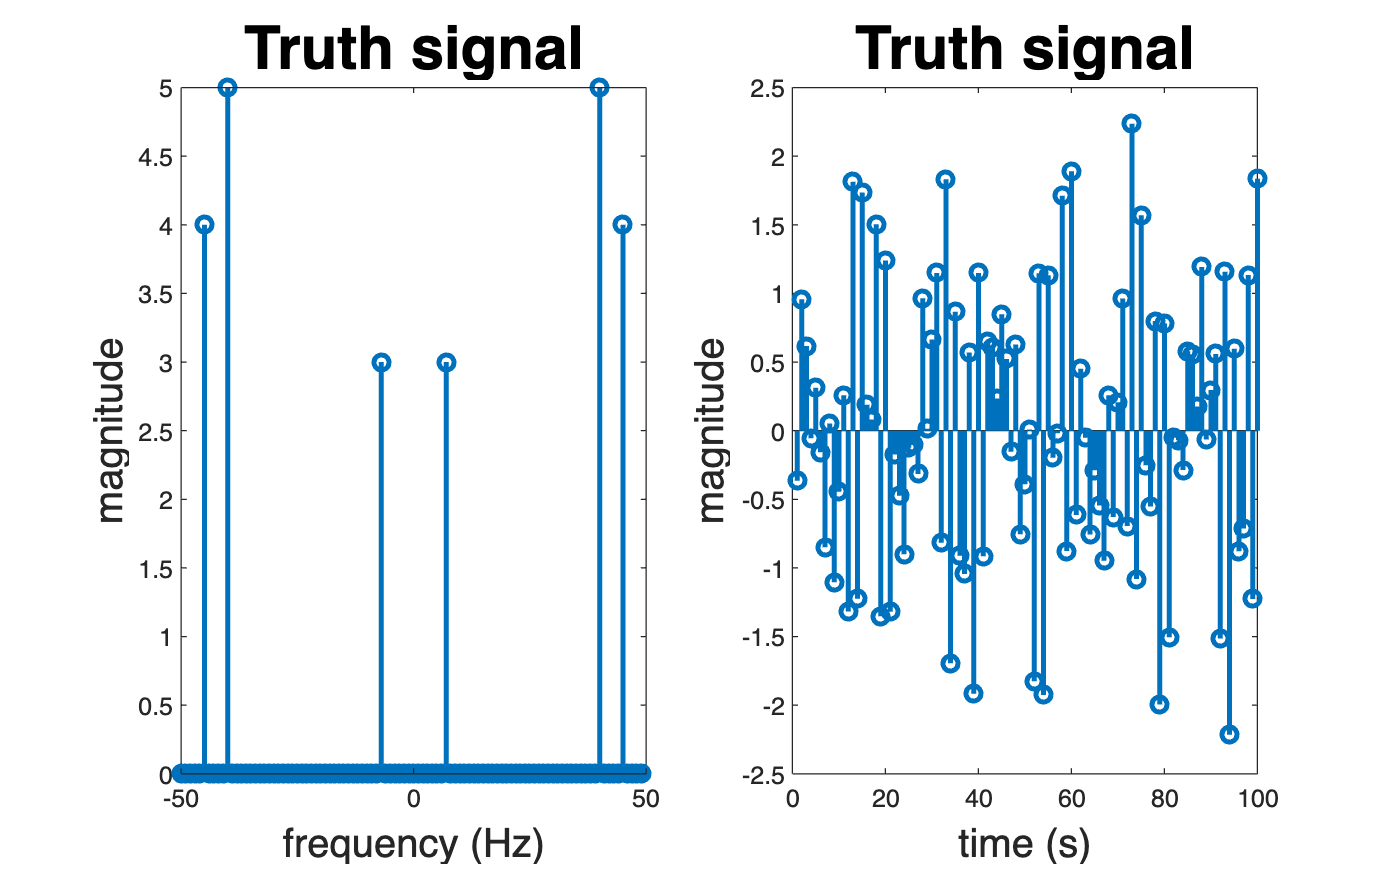

saveas(f,'plots/meas_fft.png')

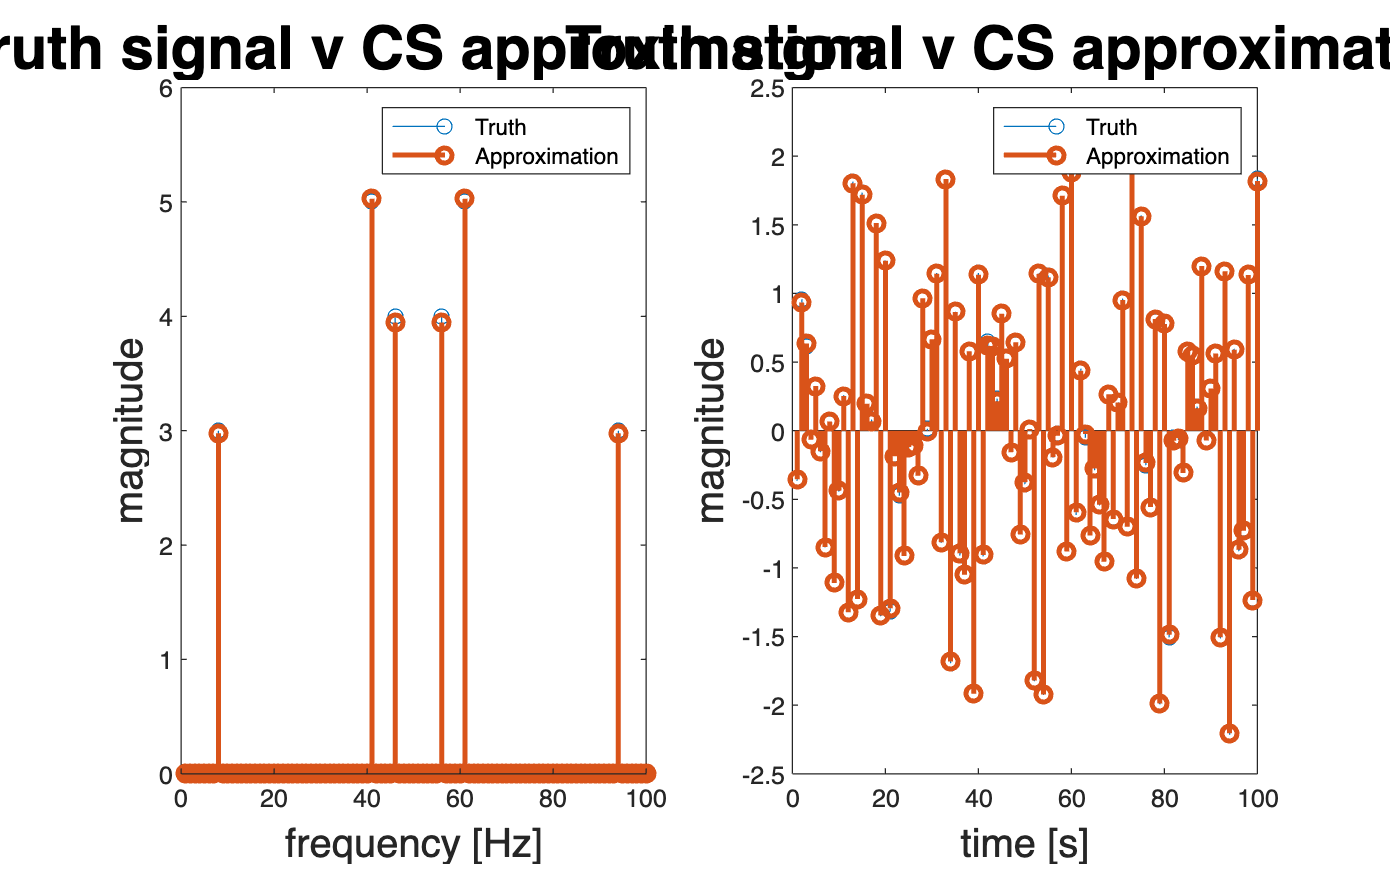

% Apply compressive sensing techniques using the orthogonal
% matching pursuit method which assumes the columns of A
% (iid Gaussian) are roughly orthogonal. The goal is to
% determine the basis vector in A that is overlaps the most
% with the measurement. This overlap is determined by an
% inner product between the measurement and each vector,
% resulting in the transformation coefficients. The greater
% the magnitude of the coefficient, the greater the overlap.
% Select the basis vector in A with the greatest inner
% product, and solve for an approximation of signal by
% minimizing || y - Ax ||_{2}^{2} using the least squares method 

% initialize the array containing the approximate non-zero
% indices
Lambda = []; X_hat = zeros(N,1);

% for now, assume we have knowledge of the number of
% nonzeros
r = y;
for i = 1:nz*2+1

    % inner product of the measurement and basis vectors
    c = A'* r;

    % find the index that maximizes the inner product
    [~, l] = max(abs(c));
    Lambda = [Lambda; l];

    % use this basis vector to calculate the least squares
    % solution
    X_hat(Lambda) = inv(A(:,Lambda)'*A(:,Lambda))*A(:,Lambda)'*y;
    r = y - A * X_hat;
end

x_hat = real(Psi * X_hat);

f = figure;
subplot(1,2,1)
stem(1:size(X,1),abs(X), 'DisplayName', 'Truth')
hold on
stem(1:size(X_hat,1),abs(X_hat),'DisplayName','Approximation', 'LineWidth',2)
title('Truth signal v CS approximation','FontSize',24)
xlabel('frequency [Hz]','FontSize',16)
ylabel('magnitude','FontSize',16)
legend

subplot(1,2,2)
stem(1:size(x,1),x, 'DisplayName', 'Truth')
hold on
stem(1:size(x_hat,1),x_hat,'DisplayName','Approximation','LineWidth',2)
title('Truth signal v CS approximation','FontSize',24)
xlabel('time [s]','FontSize',16)
ylabel('magnitude','FontSize',16)
legend
set(gcf, 'Position', get(0, 'Screensize'));
saveas(f,'plots/recon_fft.png')